# Taller 12

### 11/10/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 10 y 11*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

*Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.*

### Ejemplo sobre el uso de EDO de orden superior

...

Con esto en mente, usemos esta herramienta para analizar un sistema físico interesante, el **pendulo doble.**

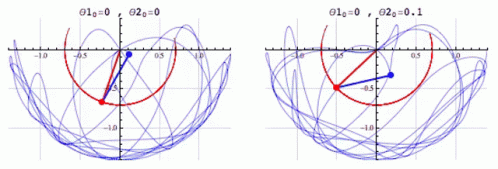

**Figura 1. ***Simulación de los efectos de la variación de las condiciones iniciales en un pendulo simple*

Este sistema es la incorporación de dos pendulos simples los cuales estan acomplados como se muestra anteriormente, realicemos el analisis de este sistema por partes, para poder establecer así una idea.

Para empezar a proceder con la propuesta del problema es necesario definir las variables a usar:

            
$$\begin{array}{l}
L\to \mathrm{Lagragiano}\\
T\to \mathrm{Energia}\;\mathrm{total}\;\mathrm{cinetica}\\
V\to \mathrm{Modulo}\;\mathrm{de}\;\mathrm{las}\;\mathrm{velocidades}\\
\theta_i \to \mathrm{Angulo}\;\mathrm{que}\;\mathrm{describe}\;\mathrm{el}\;\mathrm{pendulo}\;i\\
m_i \to \mathrm{Masa}\;\mathrm{del}\;\mathrm{pendulo}\;i\\
l_i \to \mathrm{Longuitud}\;\mathrm{del}\;\mathrm{pendulo}\;i\\
g\to \mathrm{Aceleración}\;\mathrm{de}\;\mathrm{la}\;\mathrm{gravedad}
\end{array}$$


Primeramente realicemos el cálculo de la Lagragiana $L=T-V$, con esta podemos definir que:


$$L=\frac{1}{2}\;\left(m_1 +m_2 \right){\;l_1 }^2 \;{\left(\frac{d\theta_1 }{\textrm{dt}}\right)}^2 +m_2 \;l_1 \;l_2 \;\left(\frac{d\theta_1 }{\textrm{dt}}\right)\left(\frac{d\theta_2 }{\textrm{dt}}\right)\cos \left(\theta_1 -\theta_2 \right)+\frac{1}{2}m_2 {\;l_2 }^2 \;{\left(\frac{d\theta_2 }{\textrm{dt}}\right)}^2 +\frac{1}{2}\;\left(m_1 +m_2 \right)g\;l_1 \cos \left(\theta_1 \right)+\frac{1}{2}\;m_2 \;g\;l_2 \;\cos \left(\theta_2 \right)$$


Así obtenemos las ecuaciones del movimiento:


$$\begin{array}{l}
\frac{d}{\textrm{dt}}\;\frac{\partial L}{\partial {\theta_1 }^{\prime } }-\frac{\partial L}{\partial \theta_1 }=0\\
\left(m_1 +m_2 \right){\;l_1 }^2 \;\left(\frac{d^2 \theta_1 }{{\textrm{dt}}^2 }\right)+m_2 \;l_1 \;l_2 \;\left(\frac{d^2 \theta_2 }{{\textrm{dt}}^2 }\right)\cos \left(\theta_1 -\theta_2 \right)+m_2 \;l_1 \;l_2 \;{\left(\frac{d\theta_2 }{\textrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)+\left(m_1 +m_2 \right)\;g\;l_1 \;\sin \left(\theta_1 \right)=0
\end{array}$$



$$\begin{array}{l}
\frac{d}{\textrm{dt}}\;\frac{\partial L}{\partial {\theta_2 }^{\prime } }-\frac{\partial L}{\partial \theta_2 }=0\\
m_2 \;{l_2 }^2 \;\left(\frac{d^2 \theta_2 }{{\textrm{dt}}^2 }\right)+m_2 \;l_1 \;l_2 \;\left(\frac{d^2 \theta_1 }{{\textrm{dt}}^2 }\right)\;\cos \left(\theta_1 -\theta_2 \right)-m_2 \;l_1 \;l_2 \;{\left(\frac{d\theta_1 }{\textrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)+m_2 \;g\;l_2 \;\sin \left(\theta_2 \right)=0
\end{array}$$


Aqui proponemos dividir ambas ecuaciones por $m_2 \;l_1 \;l_2 \;$, y así llamamos $m=\frac{m_1 \;}{m_2 }$.


$$\begin{array}{l}
\left(1\right)\;\;\;\left(m+1\right)\;\frac{l_1 }{l_2 }\left(\frac{d^2 \theta_1 }{{\textrm{dt}}^2 }\right)+\left(\frac{d^2 \theta_2 }{{\textrm{dt}}^2 }\right)\cos \left(\theta_1 -\theta_2 \right)+{\left(\frac{d\theta_2 }{\textrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)+\left(m+1\right)\;\frac{g}{l_2 }\;\sin \left(\theta_1 \right)=0\\
\left(2\right)\;\;\;\frac{l_2 }{l_1 }\;\left(\frac{d^2 \theta_2 }{{\textrm{dt}}^2 }\right)+\left(\frac{d^2 \theta_1 }{{\textrm{dt}}^2 }\right)\;\cos \left(\theta_1 -\theta_2 \right)-{\left(\frac{d\theta_1 }{\textrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)+\frac{g}{l_1 }\;\sin \left(\theta_2 \right)=0
\end{array}$$


Veamos que este sistema de ecuaciones de segundo orden, podemos transformarlo en un sistema de primer orden, pero antes es necesario despejar cada una de las expresiones para poder definir el sistema, así usaremos la notación:


$$\left\lbrace \begin{array}{ll}
a_1 \frac{\;d^2 \theta_1 }{{\mathrm{dt}}^2 }+b\frac{\;d^2 \theta_2 }{{\mathrm{dt}}^2 }+c_1 =0 & \;\\
a_2 \frac{\;d^2 \theta_2 }{{\mathrm{dt}}^2 }+b\frac{\;d^2 \theta_1 }{{\mathrm{dt}}^2 }+c_2 =0 & \;
\end{array}\right.$$


Así obtenemos que:


$$\begin{array}{l}
\frac{\;d^2 \theta_1 }{{\textrm{dt}}^2 }=\frac{a_2 \;c_1 -b\;c_2 }{b^2 -a_1 \;a_2 }\\
\frac{\;d^2 \theta_2 }{{\textrm{dt}}^2 }=\frac{a_1 \;c_2 -b\;c_1 }{b^2 -a_1 \;a_2 }
\end{array}$$


Con esto proponemos que:


$$U^{\prime } :={\left\lbrack \begin{array}{c}
\theta_1 \\
{\theta_1 }^{\prime } \\
\theta_2 \\
{\theta_2 }^{\prime } 
\end{array}\right\rbrack }^{\prime } =\left\lbrack \begin{array}{c}
{\theta_1 }^{\prime } \\
\frac{\cos \left(\theta_1 -\theta_2 \right)\;\left(\frac{g}{l_1 }\sin \left(\theta_2 \right)-{\left(\frac{d\theta_1 }{\mathrm{dt}}\right)}^2 \;\sin \left(\theta_1 -\theta_2 \right)\right)-\frac{l_2 }{l_1 }\left(\left(m+1\right)\frac{g}{l_2 }\sin \left(\theta_1 \right)+{\left(\frac{d\theta_2 }{\mathrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)\right)}{m+\sin^2 \left(\theta_1 -\theta_2 \right)}\\
{\theta_2 }^{\prime } \\
\frac{\cos \left(\theta_1 -\theta_2 \right)\;\left(\left(m+1\right)\frac{g}{l_2 }\sin \left(\theta_1 \right)+{\left(\frac{d\theta_2 }{\mathrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)\right)-\left(m+1\right)\frac{l_2 }{l_1 }\left(\frac{g}{l_1 }\sin \left(\theta_2 \right)+{\left(\frac{d\theta_1 }{\mathrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)\right)}{m+\sin^2 \left(\theta_1 -\theta_2 \right)}
\end{array}\right\rbrack$$


Veamos que para este sistema tenemos las herramientas para poder afrontarlo, entonces, procederemos a hallar la aproximación a la solución con los métodos anteriormente vistos, y verificaremos con la expresión de la energia total del sistema de las 2 particulas, el cual debe ser constante. Esta expresión de energía total toma la forma $E_{\textrm{total}} =E_{\textrm{Cinetica}} +E_{\textrm{Potencial}}$, esta debe ser constante ya que trabajamos con un sistema invariante:


$$E_{\textrm{Total}} =\frac{\left(m_1 +m_2 \right)}{2}\;{l_1 }^2 \;{\left(\frac{d\theta_1 }{\textrm{dt}}\right)}^2 +\frac{m_2 }{2}\;{l_2 }^2 \;{\left(\frac{d\theta_2 }{\textrm{dt}}\right)}^2 +m_2 \;l_1 \;l_2 \;\left(\frac{d\theta_1 }{\textrm{dt}}\right)\left(\frac{d\theta_2 }{\textrm{dt}}\right)\cos \left(\theta_1 -\theta_2 \right)-\left(m_1 +m_2 \right)\;g\;l_1 \;\cos \left(\theta_1 \right)-m_2 g\;l_2 \;\cos \left(\theta_2 \right)$$


clf('reset')
clear

Propongamos para cada caso la relación de masas $m$, las longuitudes de los pendulos $l_1$ y $l_2$.

m= 1;  % relación m1/m2
L1=1;
L2=2;

Ahora si la parte vital de esta aproximación, propongamos las posiciones angulares iniciales $\theta_1$ y $\theta_2$, para este caso asumiremos que ambos pendulos parten del reposo, o sea $\frac{{d\theta }_1 }{\textrm{dt}}=\frac{{d\theta }_2 }{\textrm{dt}}=0$

Seleccionar las particiones para la aproximación inicial:

    
$$\theta_1 \left(0\right)=\frac{\pi }{M},\theta_2 \left(0\right)=\frac{\pi }{N}$$


M = 6;
N = 6;
x0 = [pi/M, 0, -pi/N, 0];
tspan = [0,25];

fg = @(t,x)[x(2);
    (cos(x(1)-x(3))*(9.8*sin(x(3))/L1-x(2)^2*sin(x(1)-x(3)))-...
    (L2*((m+1)*9.8*sin(x(1))/L2+x(4)^2*sin(x(1)-x(3)))/L1))...
    /(m+sin(x(1)-x(3))*sin(x(1)-x(3)));
    x(4);
    (cos(x(1)-x(3))*((m+1)*9.8*sin(x(1))/L2+x(4)^2*sin(x(1)-x(3)))...
    -((m+1)*L1*(9.8*sin(x(3))...
    /L1-x(2)^2*sin(x(1)-x(3)))/L2))/(m+sin(x(1)-x(3))*sin(x(1)-x(3)))];

Para la solución de este sistema usaremos el método de Runge-Kutta de Orde 4.

a = tspan(1);
b = tspan(2);
F = @(t, U) fg(t, U)';
Za = x0';
M = 750;

% Método Range-kutta
Za = Za';
h = (b - a) / M;
Z = zeros(M+1, length(Za));
T = a:h:b;
Z(1, :) = Za;

for  j = 1:M
   k1 = h * feval(F, T(j), Z(j, :));
   k2 = h * feval(F, T(j) + h/2, Z(j, :) + k1/2);
   k3 = h * feval(F, T(j) + h/2, Z(j, :) + k2/2);
   k4 = h * feval(F, T(j) + h, Z(j, :) + k3);
   Z(j+1, :) = Z(j, :) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
end

for  j = 1:3
    disp("El método de RK, en la iteración " + num2str(j) + " se obtiene que:")
   k1 = h * feval(F, T(j), Z(j, :));
   k2 = h * feval(F, T(j) + h/2, Z(j, :) + k1/2);
   k3 = h * feval(F, T(j) + h/2, Z(j, :) + k2/2);
   k4 = h * feval(F, T(j) + h, Z(j, :) + k3);
   Z(j+1, :) = Z(j, :) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
   disp("Obtenemos el vector:")
   disp(Z(j+1, :)')
end

El método de RK, en la iteración 1 se obtiene que:


Obtenemos el vector:


    0.5197
   -0.2336
   -0.5213
    0.1404



El método de RK, en la iteración 2 se obtiene que:


Obtenemos el vector:


    0.5080
   -0.4690
   -0.5142
    0.2835



El método de RK, en la iteración 3 se obtiene que:


Obtenemos el vector:


    0.4884
   -0.7082
   -0.5023
    0.4318



R = [T', Z];
x = R(:, 2:5);

Para darnos una idea básica de lo que está ocurriendo, graficaremos la representación de las trayectorias $\left(\theta_1 ,\omega_1 \right)$ y $\left(\theta_2 ,\omega_2 \right)$, tener en cuenta que para este caso $\omega_i =\frac{d\theta_i }{\textrm{dt}}$, hacemos esto para poder dejar la notación en la gráfica

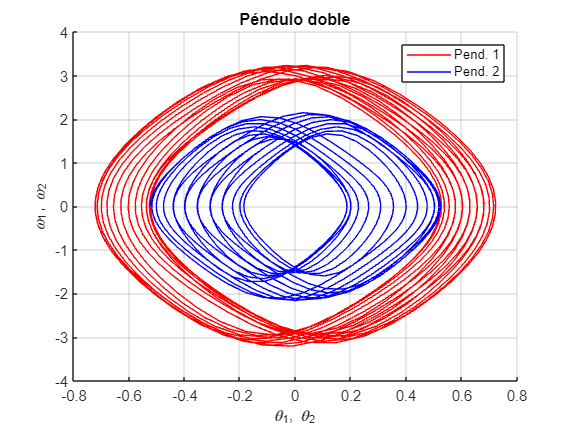

clf('reset')
hold on
plot(x(:,1),x(:,2),'r') 
plot(x(:,3),x(:,4),'b')
grid on
legend('Pend. 1','Pend. 2');
xlabel('\theta_1, \theta_2')
ylabel('\omega_1, \omega_2')
title('Péndulo doble')
hold off

Einicial=-(m+1)*9.8*cos(x0(1))/L2-9.8*cos(x0(3))/L1;

E=(m+1)*L1*x(:,2).^2/(2*L2)+L2*x(:,4).^2/(2*L1)+(x(:,2).*x(:,4))...
.*cos(x(:,1)-x(:,3))-(m+1)*9.8*cos(x(:,1))/L2-9.8*cos(x(:,3))/L1;

El error relativo que obtenemos con esta aproximación es:

ErrorRK = max(abs(100*(Einicial-E)/Einicial)) 

ErrorRK = 0.0078

Por otro lado el error que hallamos usando el método ode45.m incluido en MATLAB es:

[t,x] = ode45(fg,tspan,x0);

E=(m+1)*L1*x(:,2).^2/(2*L2)+L2*x(:,4).^2/(2*L1)+(x(:,2).*x(:,4))...
.*cos(x(:,1)-x(:,3))-(m+1)*9.8*cos(x(:,1))/L2-9.8*cos(x(:,3))/L1;

ErrorTeorico = max(abs(100*(Einicial-E)/Einicial))

ErrorTeorico = 0.5048

clear

Aquí podemos ver como los métodos que definimos en el curso pueden tener gran fuerza contra métodos que podemos encontrar por defecto con nuestras herramientas.

...

### Ecuaciones diferenciales Ordinarias de orden superior & método del disparo Lineal

#### Unos comentarios frente a los problemas de valor en la frontera

Los problemas de valor en la frontera son ecuaciones diferenciales, normalmente estas condiciones se ven en cuando se presentan derivadas parciales, y son ecuaciones donde solo se especifica las condiciones del contorno de la forma a hallar, se conocen como condiciones tipo *Dirichlet*

Para afrontar estos problemas, la estrategia que adoptaremos es reescribir el problema de frontera en problemas de valores iniciales, con pendientes adecuadas

#### PVF: Transformación a PVI equivalente

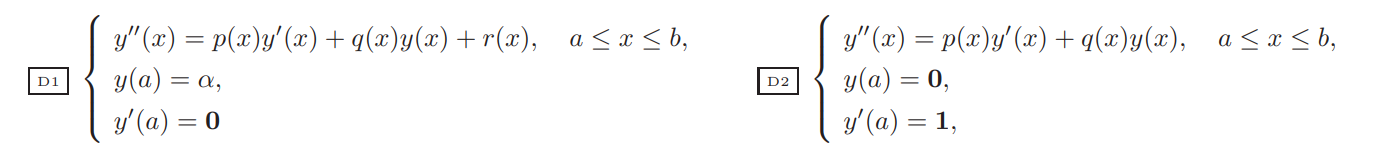

La solución hallada en D1, la notamos como $u\left(x\right)$ y D2 como $v\left(x\right)$, y la consideración de la solución:

`Nota: ``En ingenieria es común afrontar estos problemas de cualquier orden haciendo uso de los métodos de diferencias finitas.`

## Disclaimer

`Durante la grabación del taller se tuvo problemas revisando los valores que resultan tras usar una rutina vectorial dependiendo de las entradas que quedan, por lo cual al evaluar el método de disparo lineal se generaron errores. `

`TENER EN CUENTA: ``Las rutinas vectoriales son ordenadas, y entregan el mismo orden que se genera en la rutina, por lo cual si se evalua el método, empleado los cambios de variable:`

`U = [f(t, U), U(1), U(2), ...]`

`U = [U(2), U(3), ..., f(t, U)]`

`NO SE OBTIENEN LOS MISMOS RESULTADOS. ``Los vectores resultantes tienen la misma forma respectivamente Z = [`$y^{\left(n\right)}$`,` $y^{\left(n-1\right)}$`,` `..., `$y$`] y Z = [`$y$`, `$y^{\prime }$`, ...]`

`Esto no es problema si se estan revisando los resultados, pero en el método de disparo lineal linsht.m, solo se recibe el segundo cambio de variable`

### Ejercicio 5. Taller 12

Un circuito eléctrico de tipo* RLC *se modela por medio de la ecuación diferencial:


$${Q^{\prime } }^{\prime } \left(t\right)+20\;Q^{\prime } \left(t\right)+125\;Q\left(t\right)=9\;\sin \left(5t\right):Q\left(0\right)=0=Q^{\prime } \left(0\right)$$


Use el método de *Runge-Kutta* de cuarto orden para resolver esta ecuación en el intervalo $\left\lbrack 0,2\right\rbrack$ usando *M = 40* pasos o sea *h = 0.05.*

clear

F = @(t, U) [9*sin(5*t) - 20*U(1) - 125*U(2), U(1)];
Za = [0 0]; a = 0; b = 1; M = 40;

[T, Z] = rks4(F, a, b, Za, M);
[~, P] = puntomedios(F, a, b, Za, M)

P =          0         0
    0.0141         0
    0.0432    0.0006
    0.0791    0.0021
    0.1162    0.0045
    0.1505    0.0079
    0.1796    0.0120
    0.2020    0.0169
    0.2171    0.0221
    0.2245    0.0277


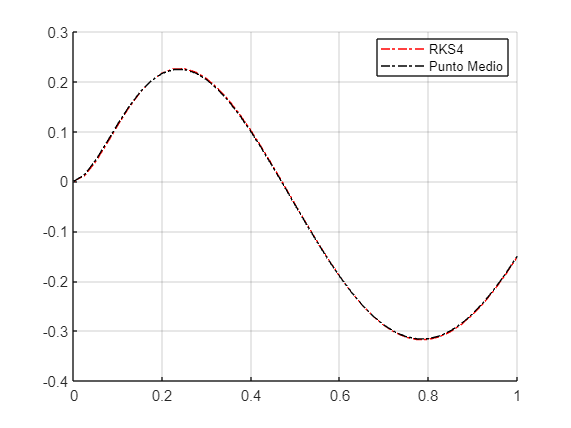


clf('reset')
hold on
plot(T, Z(:, 1), '-.r', 'DisplayName', 'RKS4')
plot(T, P(:, 1), '-.k', 'DisplayName', 'Punto Medio')
legend('Location', 'best')
grid on

### Ejercicio 5. Taller 13

Considere el PVF


$$\left\lbrace \begin{array}{ll}
{y^{\prime } }^{\prime } =\frac{y\;\left(1-x\right)+1}{{\left(1+x\right)}^2 } & 0\le x\le 1\\
y\left(0\right)=1 & y\left(1\right)=1/2
\end{array}\right.$$


Resuelva el PVF usando el método de disparo lineal, y compare los resultados obtenidos con respecto a la solución analitica $y\left(x\right)$.


$$y\left(x\right)=\frac{1}{1+x}$$


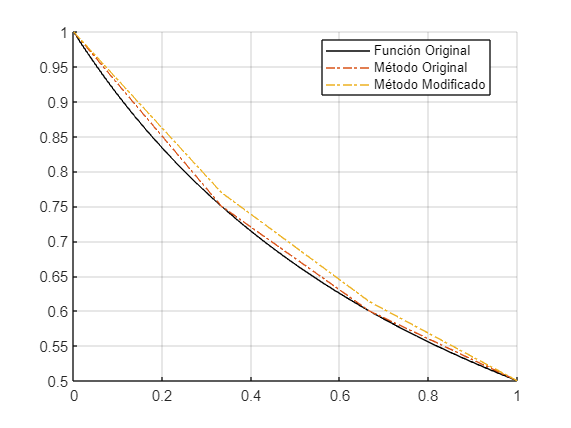

clear

F = @(x, U) [(U(2) .* (1 - x) + 1) ./ (1 + x).^2 , U(1)];

F1 = @(x, U) [U(2), 1 ./ (1 + x).^2 .*(U(1) .* (1 - x) + 1)];
F2 = @(x, U) [U(2), 1 ./ (1 + x).^2 .* (U(1) .* (1 - x))];

a = 0; b = 1; alpha = 1; beta = 1/2; M = 3;
y = @(x) 1 ./ (x + 1);

L = linsht(F1, F2, a, b, alpha, beta, M);
T = L(:, 1); YR = L(:, 2);

L = linshtMod(F1, F2, a, b, alpha, beta, M);
T = L(:, 1); YPM = L(:, 2);

clf('reset')
hold on
fplot(y, [a, b], '-k', 'DisplayName', 'Función Original')
plot(T, YR, '-.', 'DisplayName', 'Método Original')
plot(T, YPM, '-.', 'DisplayName', 'Método Modificado')
legend('Location', 'best')
hold off
grid on